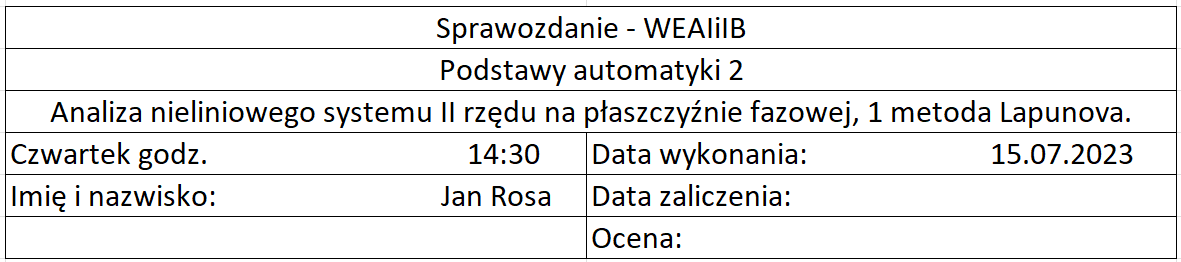

Celem tego ćwiczenia jest zapoznanie się z analizą dynamiki nieliniowych systemów drugiego rzędu przy użyciu metody płaszczyzny fazowej, zwanej również metodą Lapunova. Ćwiczenie skupia się na analizie stabilności tych systemów, które są opisane w przestrzeni stanu. Wcześniej omówiono podobną metodę w poprzednim ćwiczeniu.

Ten model opisuje na przykład ruch ciężarka na sprężynie, gdzie x(t) oznacza położenie ciężarka, współczynnik b opisuje rozpraszanie energii w układzie, a współczynniki c i d opisują nieliniową sprężynę. Gdy d = 0, otrzymujemy układ liniowy znany z poprzedniego ćwiczenia.

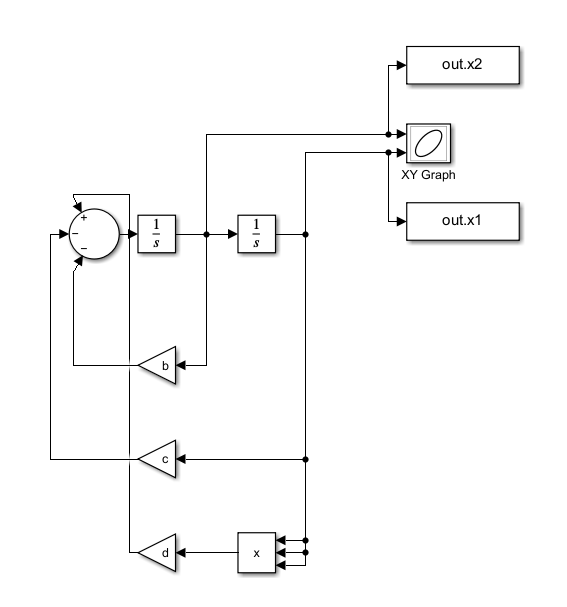

Warunki początkowe są zadawane jako warunki początkowe na całkę. Następnie generujemy portret fazowy układu dla różnych zestawów parametrów.

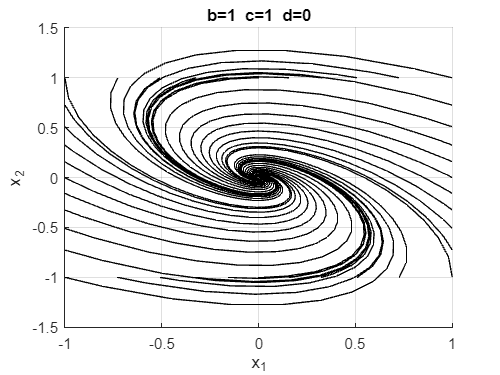

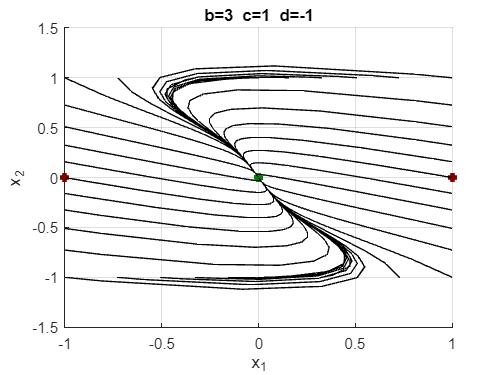

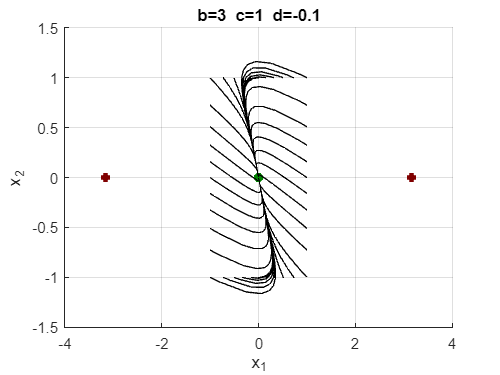

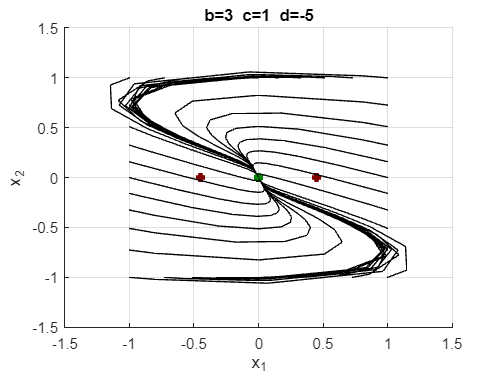

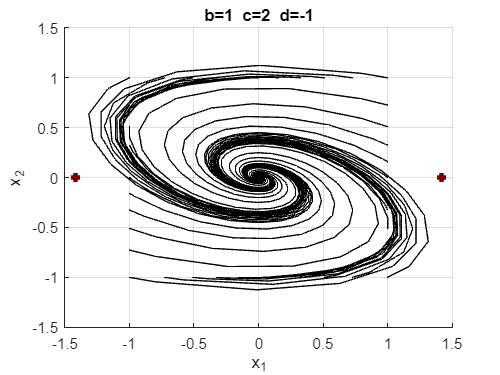

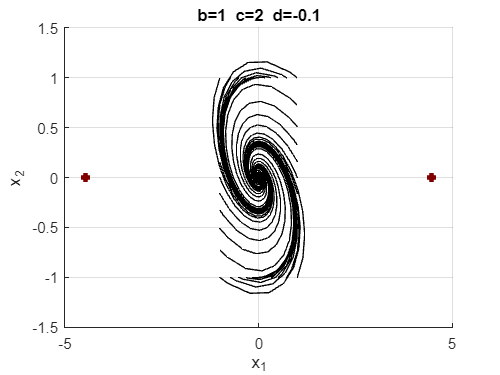

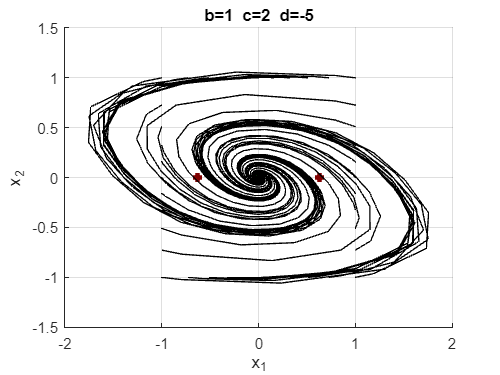

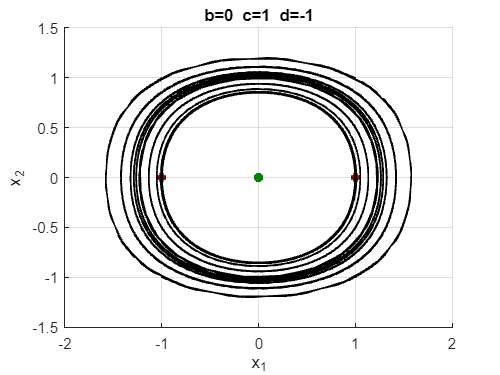

B = [1,3,3,3,1,1,1,0,0.1];
C = [1,1,1,1,2,2,2,1,2];
D = [0,-1,-0.1,-5,-1,-0.1,-5,-1,-1];

for i = 1:9
    b=B(i); 
    c=C(i);
    d=D(i); 
    T=10; 
    P=20; 
    figure;hold on; grid on;

    if d<0
     plot(sqrt(-c/d),0,'+','linewidth',3,'color',[.5 0 0]);    
     plot(-sqrt(-c/d),0,'+','linewidth',3,'color',[.5 0 0]);
     plot(0,0,'*','linewidth',3,'color',[0 .5 0]);
    end

    a=0:(pi/P):(2*pi);
    X1=[cos(a);sin(a)];
    X2=X1./[max(abs(X1));max(abs(X1))];
    M=size(X2,2);
    

    for m=1:M
     x0=X2(:,m);
     sim('simLab12', T);
     plot(ans.x2, ans.x1, 'k-', LineWidth=0.3);
     title(strcat('b=',num2str(b),'  c=',num2str(c),'  d=',num2str(d)));
     xlabel('x_1');ylabel('x_2');
    end

end

Wnioski:

1. Metoda płaszczyzny fazowej, zwana również metodą Lapunova, jest skutecznym narzędziem do analizy stabilności nieliniowych systemów drugiego rzędu opisanych równaniami różniczkowymi. Pozwala ona zobrazować dynamikę systemu na płaszczyźnie fazowej, co ułatwia identyfikację punktów równowagi oraz ocenę ich stabilności.

2. Analiza portretów fazowych układów nieliniowych pozwala na wizualne zrozumienie zachowania systemu w zależności od wartości parametrów. Dla różnych zestawów parametrów równania (1) generowane są portrety fazowe, na których zaznaczane są obszary "atrakcji" czyli obszary przyciągania asymptotycznego. Przez obserwację trajektorii wokół punktów równowagi można ocenić stabilność systemu.

3. Punkt P1 jest punktem asymptotycznie stabilnym, co oznacza, że trajektorie systemu dążą do tego punktu w miarę upływu czasu. Punkt P2 i P3 są natomiast punktami niestabilnymi, co oznacza, że trajektorie systemu oddalają się od tych punktów w miarę upływu czasu.

4. Obszar "atrakcji" punktu P1 może być przybliżony za pomocą modelowania w środowisku MATLAB/SIMULINK. Przez wygenerowanie portretów fazowych dla różnych zestawów warunków początkowych, można określić obszar, w którym trajektorie systemu będą zbliżać się do punktu P1.

5. Istnieje związek pomiędzy parametrami równania (1) a stabilnością systemu. Na przykład, eksperyment nr 1, który opisuje układ liniowy (d = 0), jest stabilny asymptotycznie. Natomiast eksperymenty nr 8 i 9, które opisują układy niestabilne asymptotycznie, mają odpowiednio d = -1 i d = -1, co spełnia warunek d < 0 dla sprężyny miękkiej.

6. Analiza stabilności nieliniowych systemów jest istotna w wielu dziedzinach, takich jak inżynieria, fizyka, biologia czy ekonomia. Metoda płaszczyzny fazowej jest jednym z narzędzi umożliwiających badanie zachowania tych systemów i może być wykorzystana do projektowania i optymalizacji układów nieliniowych.

Wnioski te potwierdzają znaczenie metody płaszczyzny fazowej w analizie stabilności nieliniowych systemów drugiego rzędu oraz jej przydatność w praktycznych zastosowaniach.